clear
clc

K = -2  0;
param = 'infinity';
I = 100;
h = 1/I;
M = 10^4;
N = 5;

x = linspace(0, 1, I+1);
x_half = zeros([I+1 1]);
for k=1:I
    x_half(k) = (x(k+1) + x(k))/2;
end

tic
rng(1)
x_hat = linspace(0, 1, N + 1);
Y = normrnd(0, 1, [N M]);
Y_IS = zeros([N M]);
%mean_shift = [1.65 0 1.36 0 -0.35 0 -0.35 0 1 0];
if K==-5 & param == 0.5
    mean_shift = [1.77 0 1.56 0 -0.38];
elseif K==-10 & param == 0.5
    mean_shift = [2.3 0 1.9 0 -0.58];
elseif K==-20 & param == 0.5
    mean_shift = [2.97 0 2.44 0 -0.94];
elseif K==-5 & param == 'infinity'
    mean_shift = [-1.5 0 -1.3 0 0.3];
elseif K==-10 & param == 'infinity'
    mean_shift = [-2.1 0 -1.93 0 0.48];
elseif K==-20 & param == 'infinity'
    mean_shift = [-2.7 0 -2.48 0 0.74];
end

for i=1:N
    rng(1)
    Y_IS(i, :) = normrnd(mean_shift(i), 1, [1 M]);
end
a = zeros([M I+1]);
a_IS = zeros([M I+1]);

% Covariance matrix construction for both h and 2h
C = Matern_specialcases_only(x_half, param);
[EVec, EVal] = eig(C);
SV = zeros([I 1]);
EVec = flip(EVec, 2);
for k=1:I
    SV(k) = sqrt(EVal(I+1-k, I+1-k));
end

for sample=1:M
% Same for M2
    inner = zeros([I+1 N]);
    inner_IS = zeros([I+1 N]);
    for k=1:N
        inner(:, k) = SV(k)*Y(k, sample).*EVec(:, k);
        inner_IS(:, k) = SV(k)*Y_IS(k, sample).*EVec(:, k);
    end
    kappa = sum(inner, 2);
    a(sample, :) = exp(kappa);
    kappa_IS = sum(inner_IS, 2);
    a_IS(sample, :) = exp(kappa_IS);
end   

F = zeros([I+1 1]);
for i=1:I+1
    F(i) = 4*pi^2*cos(2*pi*x_half(i));
end

u_h = zeros([M I+1]);
u_h_IS = zeros([M I+1]);


for sample=progress(1:M)
    A = zeros([I+1 I+1]);
    A_IS = zeros([I+1 I+1]);
    for i=2:I
       A(i, i-1) = -a(sample, i-1)/(h^2);
       A(i, i) = (a(sample, i-1) + a(sample, i+1))/(h^2);
       A(i, i+1) = -a(sample, i+1)/(h^2);
       A_IS(i, i-1) = -a_IS(sample, i-1)/(h^2);
       A_IS(i, i) = (a_IS(sample, i-1) + a_IS(sample, i+1))/(h^2);
       A_IS(i, i+1) = -a_IS(sample, i+1)/(h^2);
    end

    u_h(sample, :) = A(2:I, :)\F(2:I);
    u_h_IS(sample, :) = A_IS(2:I, :)\F(2:I);
end

Processing:  000%  |                                  | 0/10000it [00:00:00<Inf:NaN:NaN, Inf it/s]


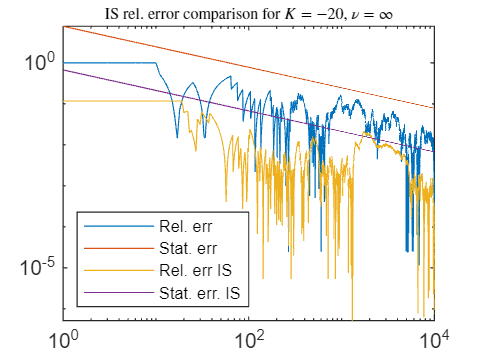


QuantOfInt = zeros([M 1]);
QuantOfInt_IS = zeros([M 1]);
for sample=1:M
    QuantOfInt(sample) = h*sum(u_h(sample, :));
    QuantOfInt_IS(sample) = h*sum(u_h_IS(sample, :));
end

%{
if K == -5
    P_ref = 0.3034;
elseif K == -10
    P_ref = 0.1589;
elseif K == -20
    P_ref = 0.0699;
end
%}
%{
P_ref_K5 = 0.3034;
P_ref_K10 = 0.1589;
P_ref_K20 = 0.0699;
%}

c_alpha = 1.96;
P_K = zeros([1 M]);
var = zeros([1 M]);
rel_err = zeros([1 M]);
stat_err = zeros([1 M]);
P_K_IS = zeros([1 M]);
var_IS = zeros([1 M]);
rel_err_IS = zeros([1 M]);
stat_err_IS = zeros([1 M]);
for k=1:M
    P_K(k) = 1/k*sum(QuantOfInt(1:k)<K);
    P_K_IS(k) = 1/k*sum(QuantOfInt_IS(1:k)<K);
end
P_ref = P_K(end);
P_ref_IS = P_K_IS(end);

for k=1:M

    if k>1
        var(k) = 1/(k-1)*sum(((QuantOfInt(1:k)<K) - P_ref).^2);
        var_IS(k) = 1/(k-1)*sum(((QuantOfInt_IS(1:k)<K) - P_ref_IS).^2);
    end
    
    rel_err(k) = abs(P_K(k) - P_ref)/abs(P_ref);
    rel_err_IS(k) = abs(P_K_IS(k) - P_ref_IS)/abs(P_ref_IS);
end

for k=1:M
    stat_err(k) = c_alpha*sqrt(var(end))/(sqrt(k)*abs(P_ref));
    stat_err_IS(k) = c_alpha*sqrt(var_IS(end))/(sqrt(k)*abs(P_ref_IS));
end

loglog(1:M, rel_err, 1:M, stat_err, 1:M, rel_err_IS, 1:M, stat_err_IS)
legend('Rel. err', 'Stat. err', 'Rel. err IS', 'Stat. err. IS', location='southwest', fontsize=7)
title('IS rel. error comparison for $K=-20$, $\nu=\infty$', 'Interpreter', 'latex', fontsize=7)
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "IS_inf_K20")


toc

Elapsed time is 8.431613 seconds.
